# [无人机包裹递送](https://ww2.mathworks.cn/help/releases/R2022b/uav/ug/uav-package-delivery.html)

此示例展示了通过增量设计迭代，了解如何实现小型多旋翼飞行器仿真，以在城市环境中的不同位置起飞、飞行和着陆。

## 打开项目

首先，打开示例实时脚本并通过单击文档中的 **Open Live Script** 或使用该函数来访问支持文件。

然后，打开 Simulink™ 项目文件。

prj = openProject('uavPackageDelivery.prj');

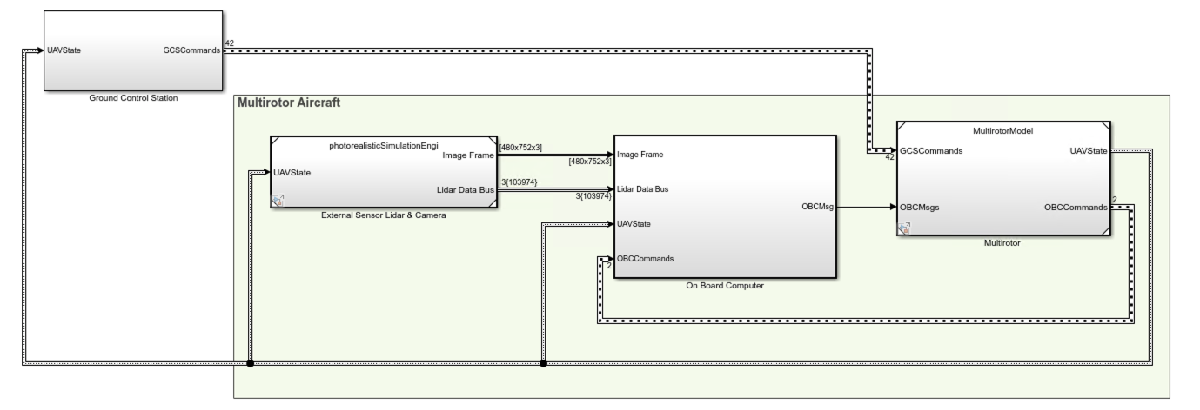

## 模型架构和约定

顶层模型由以下子系统和模型参考组成：

- **Ground Control Station:**  用于在飞行中控制和监控飞机。

- **External Sensors - Lidar & Camera:** 用于连接到先前设计的场景或真实感仿真环境。当飞机飞过环境时，这些传感器会产生环境中的激光雷达读数。

- **On Board Computer:** 用于实现在独立于自动驾驶仪的机载计算机中运行的算法。

- **Multirotor: **包括低保真度和中保真度多旋翼飞行器模式、飞行控制器及其引导逻辑。   

模型的设计数据包含在 **data** 文件夹 (`uavPackageDeliveryDataDict.sldd`) 的 Simulink™数据字典中。此外，该模型还使用使用变体子系统 [**Variants**](docid:simulink_ug#bvhtavr) 在单独的层次结构中实现变体来管理模型的不同配置。放置在基础工作区中的变量可以配置这些变体，而无需修改数据字典。

## 遵循示例的步骤

使用项目快捷方式 **Project Shortcuts** (位于utilities\shortcut_scripts\)逐步完成该示例。每个快捷方式都会设置项目所需的变量。

## 1. 入门

单击 **Getting Started** 项目快捷方式，该快捷方式使用低保真多旋翼植物模型设置用于四航点任务的模型。运行 **Run** 模型 `uavPackageDelivery` ，该模型以三维绘图形式显示多旋翼飞行器的起飞、飞行和着陆过程。

 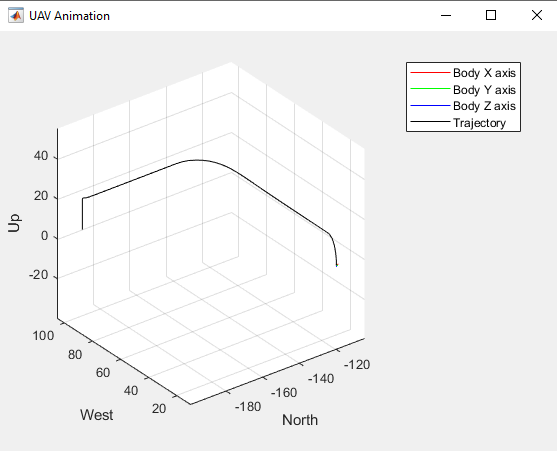

该模型使用 **UAV Path Manager** 模块来确定哪个是整个飞行过程中的活动航路点。活动航路点被传递到制 **Guidance Mode Selector** Stateflow™ 图中，以生成必要的内环控制命令。

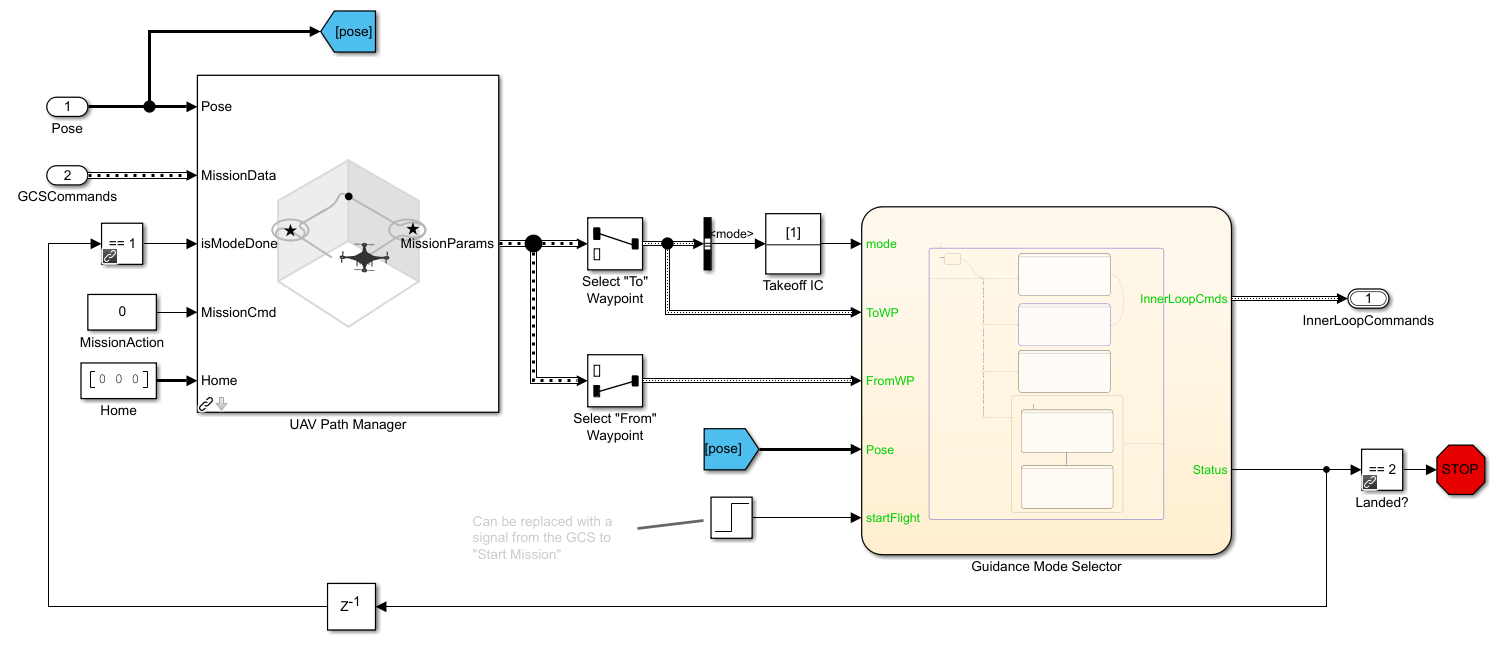

## **2. 连接地面站**

一旦能够执行基本任务，就可以将仿真与地面站软件集成，以便可以更好地控制飞机的任务。为此，需要下载并安装地面控制站软件 [QGroundControl](http://qgroundcontrol.com/) 。

该模型使用 UAV Toolbox™ [MAVLink Support](docid:uav_ref#mw_a42d7e4d-a619-464d-9689-b0efba50ee94) 在 Simulink 和 QGroundControl 之间建立连接。该连接是由 MATLAB® System Block 实现，位于 `uavPackageDelivery/Ground Control Station/Get Flight Mission/QGC/MAVLink Interface`。

要测试 Simulink 和 QGroundControl 之间的连接，请按照以下步骤操作：

- 单击连接到 **Connecting to a GCS** 项目快捷方式。

- 启动 QGroundControl。

- 在 QGroundControl 中，加载位于 `/utilities/qgc `名为 `shortMission.plan` 的任务计划。

- **Run** 仿真。

- 当 QGroundControl 表明已连接到系统时，上传任务。

飞机起飞后，应该看到无人机按照 QGC 发送的任务执行任务，如下所示。

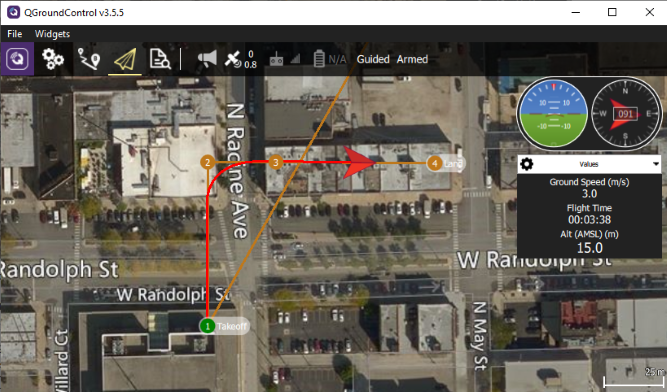

可以通过添加航点或移动任务中已有的航点来修改任务。上传任务，飞机应该对这些变化做出反应。

## 3. 设置长方体场景

现在飞机模型可以从地面控制站传输，请考虑飞机飞行的环境。在本例中，使用 [`uavScenario`](docid:uav_ref#mw_a038cc32-74b4-4d65-a325-1a8dae51a1c7) 对象在长方体场景中对一些城市街区进行建模。该场景基于下左图所示的城市街区。

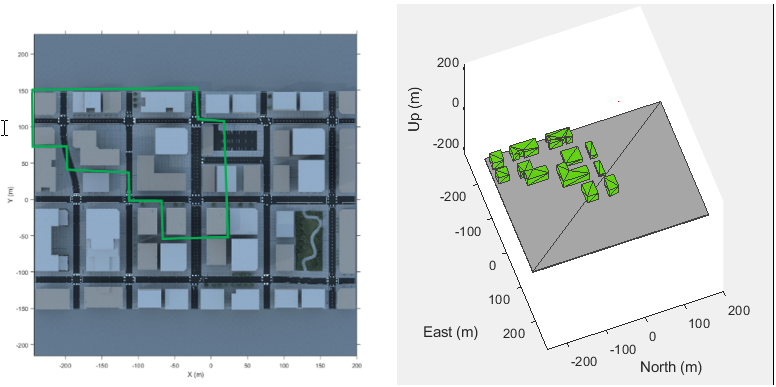

为了在这种情况下安全地驾驶飞机，需要一个向模型提供有关环境信息的传感器，例如激光雷达传感器。本示例使用一个 `uavLidarPointCloudGenerator` 对象添加到带 `uavSensor` 无人机场景中。激光雷达传感器模型根据传感器的姿态和环境中的障碍物生成读数。

单击 **Setting a Cuboid Scenario** 快捷方式并 **Run** 模型。模型运行时，飞机飞过长方体环境时会显示激光雷达点云图像：

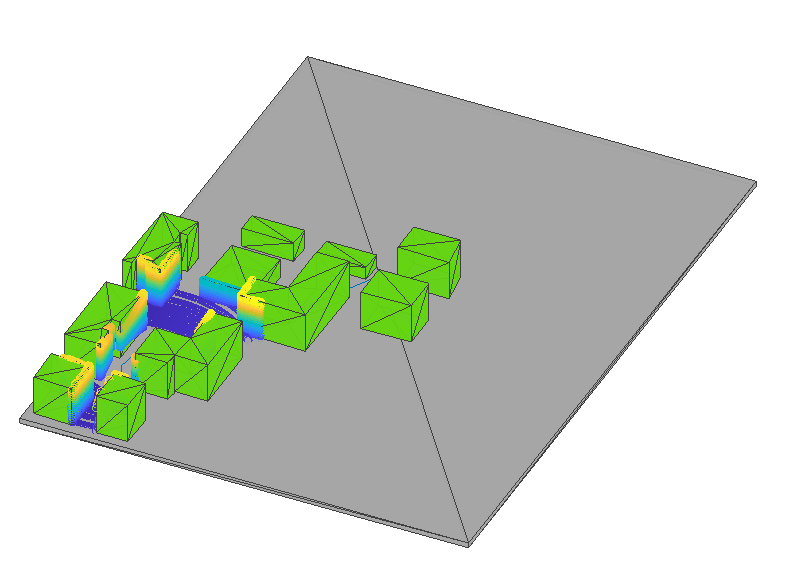

## 4. 避障

在当前目录（工程目录）运行 utilities\shortcut_scripts\step_5_photorealisticSimulation.m

为了避开环境中的障碍物，模型必须在无人机在环境中执行任务时使用可用的传感器数据。要修改模型配置，请单击 **Obstacle Avoidance** 或 **3D Obstacle Avoidance **快捷方式。出现一个范围，显示长方体环境中距建筑物最近的点。**Obstacle Avoidance **快捷方式将模型配置为使用平面激光雷达信息和 [**Vector Field Histogram block**](docid:nav_ref#bvam7nc) ，通过改变无人机在当前 x-y 平面中的方向来避开障碍物。**3D Obstacle Avoidance** 快捷方式将模型配置为使用三维激光雷达点和 [**Obstacle Avoidance block**](docid:uav_ref#mw_5efb91c2-4a01-4ae1-9e05-287bdcf49a89)，通过改变无人机在三维空间中的方向来避开障碍物。

**运行**模型。在**避障**模式下，当模型运行时，飞机会尝试沿建筑物之间的直线路径飞行到降落地点，但会偏离航线以避开沿途的障碍物。观察与障碍物的距离随时间的变化，并在**三维避障**模式下观察类似的行为，无人机现在还能够调整高度以飞越障碍物。

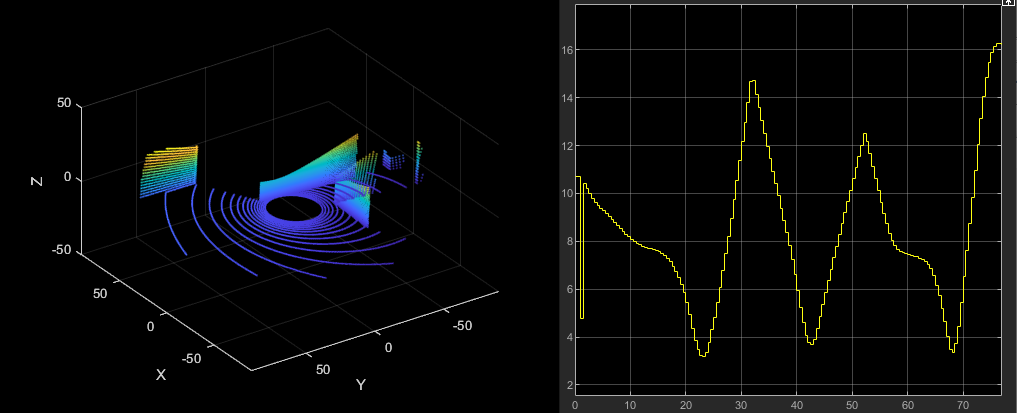

## 5. 照片级仿真

到目前为止，环境是一个简单的长方体场景。要提高环境的保真度，请单击 **Photorealistic Simulation** 快捷方式，这会将飞机置于更真实的世界中飞行。位于 `uavPackageDelivery/photorealisticSimulationEngi/SimulationEnvironmentVariant` 的 PhotorealisticQuadrotor 变体变成活动状态。该变体包含配置仿真环境和安装在飞机上的传感器所需的块：

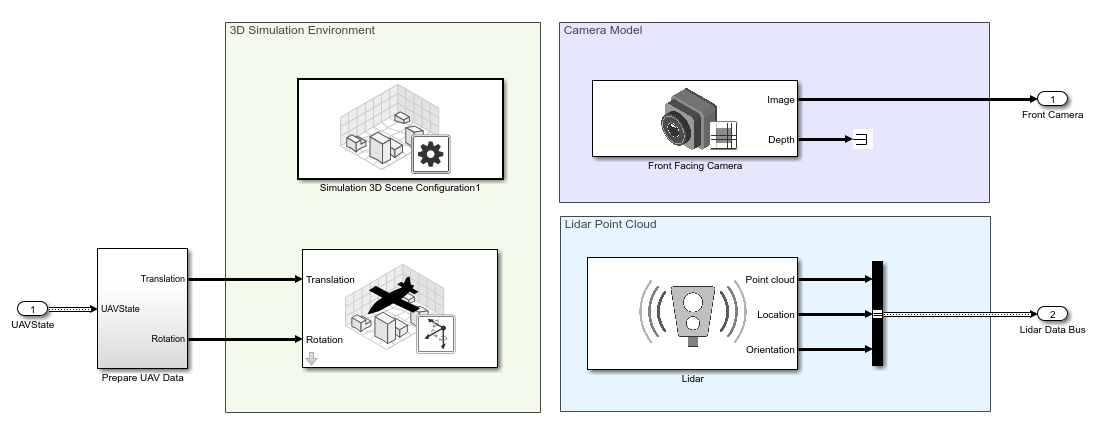

运行模型。飞机被设置为执行步骤 1 和 2 中的相同任务。请注意，当飞机执行任务时，激光雷达点云会更新，并显示来自前置摄像头的图像。

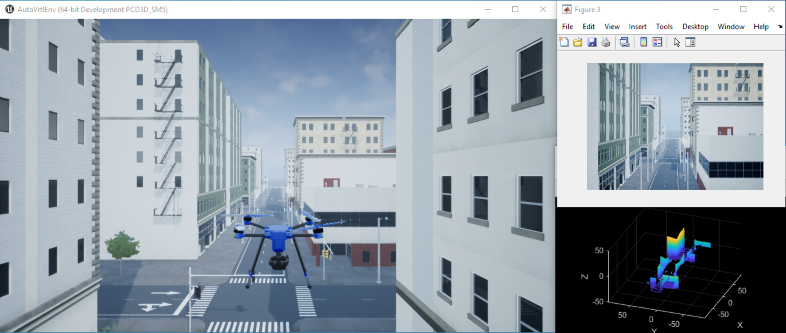

## 6. 在照片级仿真环境中完成任务

接下来，单击 **Fly full mission** 快捷方式，该快捷方式设置与步骤 2 中的 QGroundControl 的连接，以便在逼真的环境中上传任务。请按照以下步骤运行模拟：

- 启动 QGroundControl。

- 在 QGroundControl中，加载位于 `/utilities/qgc` 名为 `shortMission.plan` 的任务计划`。`

- 运行仿真。

- 当 QGroundControl 指示它已连接到系统时，上传任务。

当飞机开始飞行时，可以通过添加航路点或移动任务中已有的航路点来修改 QGroundControl 中的任务。上传任务，飞机应该对这些变化做出反应。在整个飞行过程中，将看到飞机在场景中飞行。

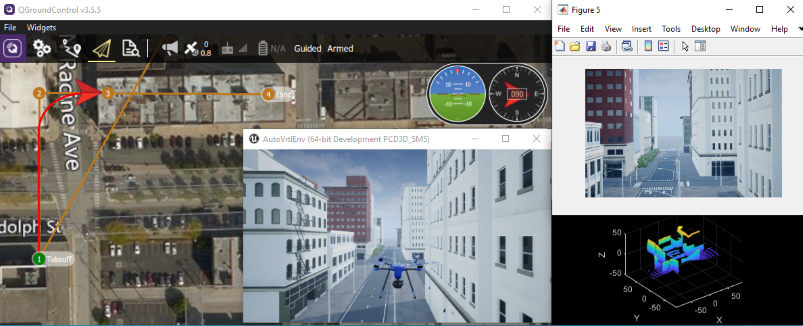

## 7. 照片级仿真环境中的飞行避障

接下来，目标是通过在 QGroundControl 中指定起飞和着陆点并使用避障功能绕过路径上的障碍物来执行任务。单击 **Fly full Obstacle Avoidance **或** Fly full 3D Obstacle Avoidance** 快捷方式，然后按照以下步骤运行仿真：

- 启动 QGroundControl。

- 在 QGroundControl 中，加载位于 `/utilities/qgc `名为 `oaMission.plan` 的任务计划。

- **运行**仿真。

- 当 QGroundControl 指示它已连接到系统时，上传任务。

在整个飞行过程中，观察飞机尝试遵循 QGroundControl 中的命令路径，同时尝试避免与环境中的建筑物发生碰撞。如果使用 **Fly full 3D Obstacle Avoidance**，可以观察到无人机飞过较低的建筑物而不是周围。

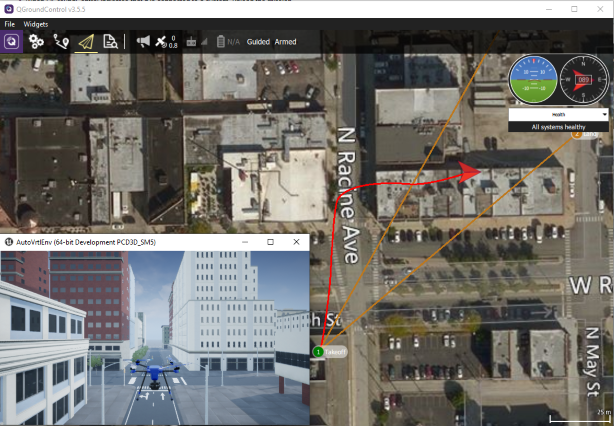

在飞行过程中的某个时刻，会看到无人机在建筑物拐角处飞行。

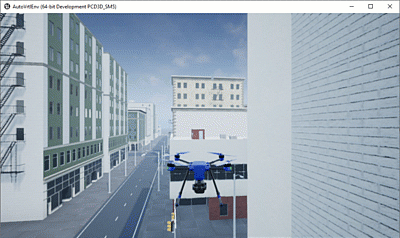

## 8. 添加 6DOF 植物模型以实现更高保真度的仿真 

最后一步，单击 **Adding a High Fidelity Plant** 快捷方式，这将激活位于 `uavPackageDelivery/MultirotorModel/Inner Loop and Plant Model/High-FidelityModel`.的UAV模型的高保真变体。 该变体包含一个内环控制器和一个高保真对象模型。

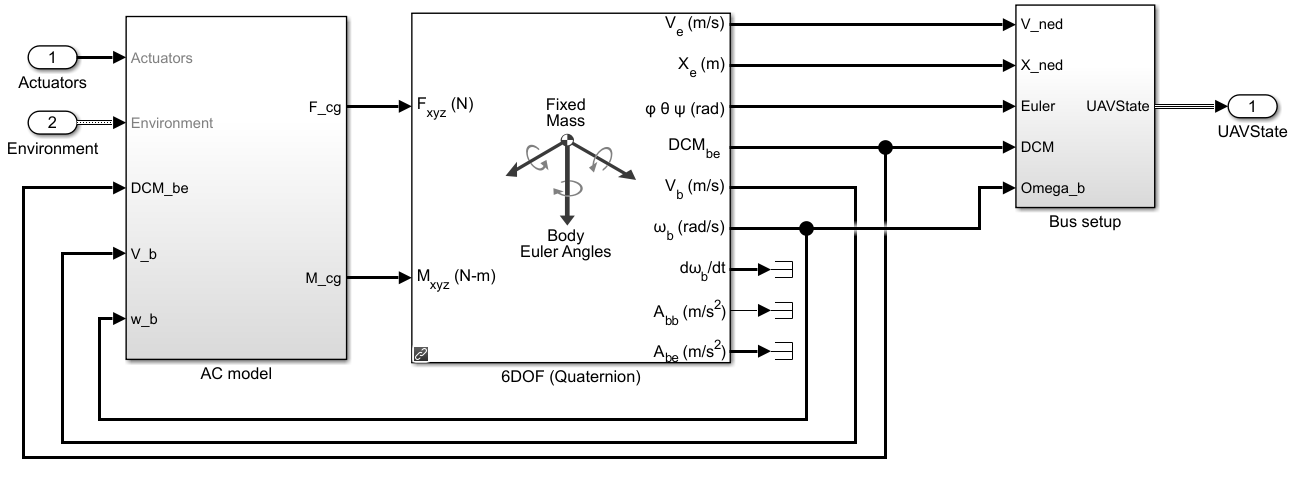

**运行**模型。由于高保真模型，行为略有变化，但无人机执行相同的任务。

探索完模型后，关闭项目文件。

close(prj);

*Copyright 2020-2021 The MathWorks, Inc.*